syms t w;
f(t,w) = 1 + w/t;
y(t) = t*log(t) + 2*t;

for h=[1/10, 1/20, 1/40]
    [~, y_values] = Exact_Values(h, y);
    [t_values, w_values] = Adams_4th_Order_Predictor_Corrector(h, f);
    [error_values, max_error] = Error(y_values, w_values);
    fprintf('----------------------------------------------------\n');
    fprintf('Adams 4th-order predictor-corrector method with h=1/%d:\n', 1/h);
    fprintf('Approximated values are:\n');
    disp(w_values)
    fprintf('Absolute errors for each values are\n');
    disp(error_values);
    fprintf('Maximum absolute error is: %e\n', max_error)
end

----------------------------------------------------


Adams 4th-order predictor-corrector method with h=1/10:


Approximated values are:


    2.0000    2.3048    2.6188    2.9411    3.2711    3.6082    3.9520    4.3021    4.6580    5.0195    5.3863



Absolute errors for each values are


   1.0e-05 *

         0    0.0272    0.0485    0.0661    0.1046    0.0732    0.0686    0.0730    0.0723    0.0753    0.0805



Maximum absolute error is: 1.046104e-06


----------------------------------------------------


Adams 4th-order predictor-corrector method with h=1/20:


Approximated values are:


    2.0000    2.1512    2.3048    2.4607    2.6188    2.7789    2.9411    3.1051    3.2711    3.4388    3.6082    3.7793    3.9520    4.1263    4.3021    4.4793    4.6580    4.8381    5.0195    5.2023    5.3863



Absolute errors for each values are


   1.0e-06 *

         0    0.0094    0.0176    0.0249    0.0488    0.0540    0.0636    0.0733    0.0815    0.0899    0.0982    0.1061    0.1137    0.1212    0.1284    0.1354    0.1423    0.1489    0.1555    0.1619    0.1681



Maximum absolute error is: 1.681222e-07


----------------------------------------------------


Adams 4th-order predictor-corrector method with h=1/40:


Approximated values are:


    2.0000    2.0753    2.1512    2.2277    2.3048    2.3825    2.4607    2.5395    2.6188    2.6986    2.7789    2.8598    2.9411    3.0229    3.1051    3.1879    3.2711    3.3547    3.4388    3.5233    3.6082    3.6935    3.7793    3.8655    3.9520    4.0390    4.1263    4.2140    4.3021    4.3905    4.4793    4.5685    4.6580    4.7479    4.8381    4.9286    5.0195    5.1107    5.2023    5.2941    5.3863



Absolute errors for each values are


   1.0e-07 *

         0    0.0031    0.0060    0.0087    0.0193    0.0261    0.0333    0.0402    0.0466    0.0528    0.0587    0.0644    0.0699    0.0751    0.0802    0.0852    0.0899    0.0945    0.0990    0.1034    0.1076    0.1117    0.1158    0.1197    0.1236    0.1273    0.1310    0.1347    0.1382    0.1418    0.1452    0.1486    0.1520    0.1553    0.1585    0.1617    0.1649    0.1680    0.1712    0.1742    0.1773



Maximum absolute error is: 1.772807e-08


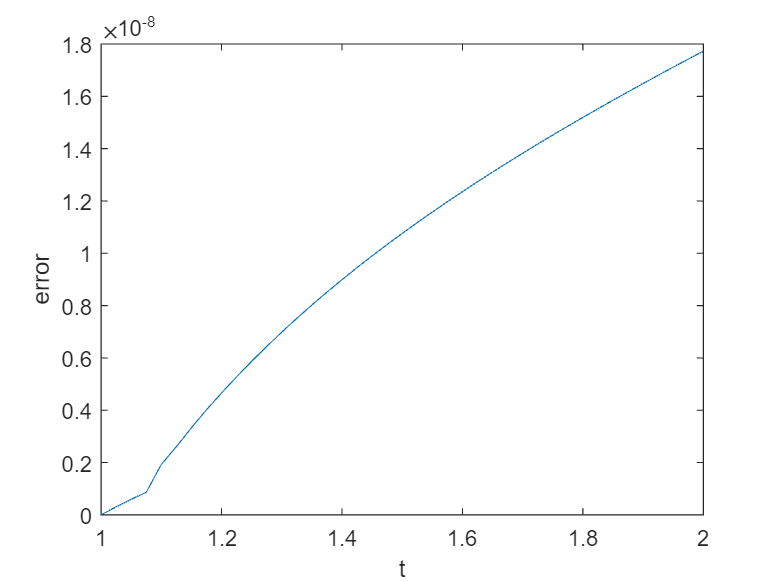


% last t_values and error_values are saved
% they are values associated with h=1/40
plot(t_values, error_values)
xlabel('t');
ylabel('error');

function [t_values, w_values] = Adams_4th_Order_Predictor_Corrector(h, f)
    % for speed, i did preallocation
    numbs = 1/h + 1;
    t_values = 1:h:2;
    w_values = zeros(1, numbs);

    t = 1;
    w = 2;
    w_values(1) = w;

    % RK4 for starting values
    for i=2:4
        K1 = h * f(t,w);
        K2 = h * f(t+h/2, w+K1/2);
        K3 = h * f(t+h/2, w+K2/2);
        K4 = h * f(t+h, w+K3);
        w = w + (K1+2*K2+2*K3+K4)/6;
        t = t + h;

        w_values(i) = w;
    end

    % Set starting pts
    f0 = f(t_values(1), w_values(1));
    f1 = f(t_values(2), w_values(2));
    f2 = f(t_values(3), w_values(3));
    f3 = f(t_values(4), w_values(4));
    w3 = w_values(4);

    % Do predictor corrector method
    for i=5:numbs
        t = t + h;
        % predict w_i
        w = w3 + h*(55*f3-59*f2+37*f1-9*f0)/24;
        % correct w_i
        fw = f(t, w);
        w = w3 + h*(9*fw+19*f3-5*f2+f1)/24;

        w_values(i) = w;

        % reset values for iteration
        f0 = f1;
        f1 = f2;
        f2 = f3;
        f3 = fw;
        w3 = w;
    end
end

function [t_values, y_values] = Exact_Values(h, y)
    % for speed, i did preallocation
    numbs = 1/h + 1;
    t_values = 1:h:2;
    y_values = zeros(1, numbs);

    t = 1;
    for i=1:numbs
        y_values(i) = y(t);
        t = t + h;
    end
end

function [error_values, max_error] = Error(exact_values, approx_values)
    error_values = abs(exact_values - approx_values);
    max_error = max(error_values);
end